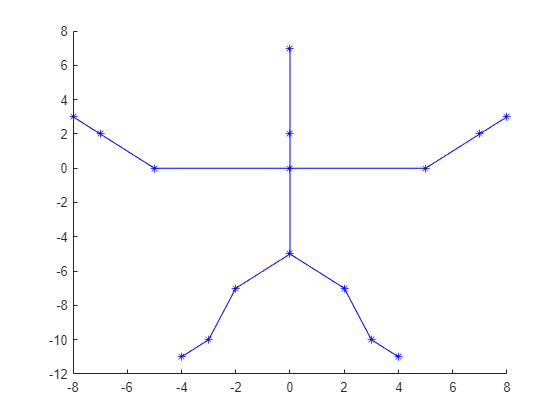

clear

% Section1: build skeleton
head = [0, 0; 2, 7];
neck = [0, 0; 0, 2];
left_upper_arm = [0, -5; 0, 0];
left_forearm = [-5, -7; 0, 2];
left_hand = [-7, -8; 2, 3];
right_upper_arm = [0, 5; 0, 0];
right_forearm = [5, 7; 0, 2];
right_hand = [7, 8; 2, 3];
body = [0, 0; 0, -5];
left_thigh = [0, -2; -5, -7];
left_lower_leg = [-2, -3; -7, -10];
left_feet = [-3, -4; -10, -11];
right_thigh = [0, 2; -5, -7];
right_lower_leg = [2, 3; -7, -10];
right_feet = [3, 4; -10, -11];
skeleton = {head, neck, left_upper_arm, left_forearm, left_hand, right_upper_arm, right_forearm, right_hand, body, left_thigh, left_lower_leg, left_feet, right_thigh, right_lower_leg, right_feet};

% plot
clf
figure(1)
hold on;
for i = 1:15
    tmp = cell2mat(skeleton(i));
    plot(tmp(1,1:end), tmp(2,1:end),'*b-')
end


% Section2: rotate left_upper_arm, left_forearm and left_hand
% Enter your code here
l_upper_theta =0

l_upper_theta = 0

l_upper_rotation = [cosd(l_upper_theta), sind(l_upper_theta); -sind(l_upper_theta), cosd(l_upper_theta)];

%rotationg left upperarm,
movement = l_upper_rotation * cell2mat(skeleton(3));
change = movement - cell2mat(skeleton(3)); %save for using to move connected bones
skeleton(3) = mat2cell(movement,2,2);

%move left forearm and hand
change = change(:, 2); %x-axis rotation, hence only y coords change
skeleton(4) = mat2cell(cell2mat(skeleton(4)) + change,2,2);
skeleton(5) = mat2cell(cell2mat(skeleton(5)) + change,2,2);

%rotate and move left forearm
l_fore_theta =0

l_fore_theta = 0

l_fore_rotation = [cosd(l_fore_theta), sind(l_fore_theta); -sind(l_fore_theta), cosd(l_fore_theta)];
old_pos = cell2mat(skeleton(4));
new_pos = old_pos - old_pos(:,1); %move to 0,0 for rotation
new_pos = l_fore_rotation * new_pos;
new_pos = new_pos + old_pos(:,1);
move = new_pos(:,2) - old_pos(:, 2);
skeleton(4) = mat2cell(new_pos,2,2);
%move left hand
skeleton(5) = mat2cell(cell2mat(skeleton(5)) + move,2,2);
%rotating left forearm also rotates left hand by same amount

l_hand_theta =0

l_hand_theta = 0

l_hand_rotation = [cosd(l_hand_theta), sind(l_hand_theta); -sind(l_hand_theta), cosd(l_hand_theta)]

l_hand_rotation =      1     0
     0     1



old_pos = cell2mat(skeleton(5));
new_pos = old_pos - old_pos(:,1);
new_pos = l_hand_rotation * new_pos;
new_pos = new_pos + old_pos(:,1);
skeleton(5) = mat2cell(new_pos,2,2);
% Plot the result
% Enter your code here

clf
figure(1)
hold on;
for i = 1:15
    tmp = cell2mat(skeleton(i));
    plot(tmp(1,1:end), tmp(2,1:end),'*b-')
end


% Section3: rotate right_upper_arm, right_forearm and right_hand
% Enter your code here
r_upper_theta = 0

r_upper_theta = 0

r_upper_rotation = [cosd(r_upper_theta), sind(r_upper_theta); -sind(r_upper_theta), cosd(r_upper_theta)];

%rotationg left upperarm,
movement = r_upper_rotation * cell2mat(skeleton(6));
change = movement - cell2mat(skeleton(6)); %save for using to move connected bones
skeleton(6) = mat2cell(movement,2,2);

%move left forearm and hand
change = change(:, 2); %x-axis rotation, hence only y coords change
skeleton(7) = mat2cell(cell2mat(skeleton(7)) + change,2,2);
skeleton(8) = mat2cell(cell2mat(skeleton(8)) + change,2,2);

%rotate and move left forearm
r_fore_theta = 0

r_fore_theta = 0

r_fore_rotation = [cosd(r_fore_theta), sind(r_fore_theta); -sind(r_fore_theta), cosd(r_fore_theta)];
old_pos = cell2mat(skeleton(7));
new_pos = old_pos - old_pos(:,1); %move to 0,0 for rotation
new_pos = r_fore_rotation * new_pos;
new_pos = new_pos + old_pos(:,1);
move = new_pos(:,2) - old_pos(:, 2);
skeleton(7) = mat2cell(new_pos,2,2);
%move left hand
skeleton(8) = mat2cell(cell2mat(skeleton(8)) + move,2,2);
%rotating left forearm also rotates left hand by same amount

r_hand_theta = 0

r_hand_theta = 0

r_hand_rotation = [cosd(r_hand_theta), sind(r_hand_theta); -sind(r_hand_theta), cosd(r_hand_theta)]

r_hand_rotation =      1     0
     0     1



old_pos = cell2mat(skeleton(8));
new_pos = old_pos - old_pos(:,1);
new_pos = r_hand_rotation * new_pos;
new_pos = new_pos + old_pos(:,1);
skeleton(8) = mat2cell(new_pos,2,2);
% Plot the result
% Enter your code here

clf
figure(1)
hold on;
for i = 1:15
    tmp = cell2mat(skeleton(i));
    plot(tmp(1,1:end), tmp(2,1:end),'*b-')
end


% Section4: rotate the body and update the related body part
% Enter your code here
body_theta =-30

body_theta = -30

body_rotation = [cosd(body_theta), sind(body_theta); -sind(body_theta), cosd(body_theta)];

%rotationg left upperarm,
movement = body_rotation * cell2mat(skeleton(9));
change = movement - cell2mat(skeleton(9)); %save for using to move connected bones
skeleton(9) = mat2cell(movement,2,2)

skeleton = 1×15 cell array
    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}


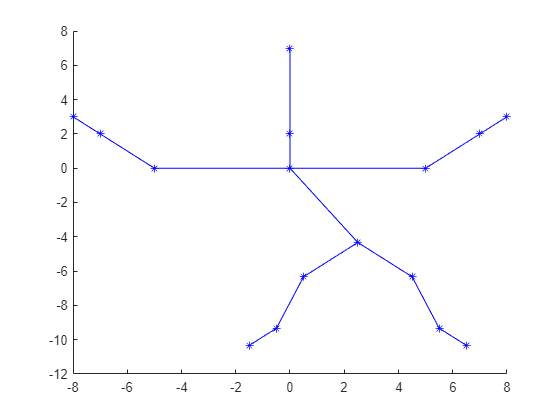


change = change(:,2); %x-axis rotation, hence only y coords change
skeleton(10) = mat2cell(cell2mat(skeleton(10)) + change,2,2);
skeleton(11) = mat2cell(cell2mat(skeleton(11)) + change,2,2);
skeleton(12) = mat2cell(cell2mat(skeleton(12)) + change,2,2);
skeleton(13) = mat2cell(cell2mat(skeleton(13)) + change,2,2);
skeleton(14) = mat2cell(cell2mat(skeleton(14)) + change,2,2);
skeleton(15) = mat2cell(cell2mat(skeleton(15)) + change,2,2);

% Plot the result
% Enter your code here
clf
figure(1)
hold on;
for i = 1:15
    tmp = cell2mat(skeleton(i));
    plot(tmp(1,1:end), tmp(2,1:end),'*b-')
end


% Section5: rotate left_thigh, left_lower_leg and left_feet
% Enter your code here
l_thigh_theta =0

l_thigh_theta = 0

l_thigh_rotation = [cosd(l_thigh_theta), sind(l_thigh_theta); -sind(l_thigh_theta), cosd(l_thigh_theta)];

%rotationg left upperarm,
old_pos = cell2mat(skeleton(10));
new_pos = old_pos - old_pos(:,1); %move to 0,0 for rotation
new_pos = l_thigh_rotation * new_pos;
new_pos = new_pos + old_pos(:,1);
change = new_pos(:,2) - old_pos(:, 2);
skeleton(10) = mat2cell(new_pos,2,2);

%move left forearm and hand
skeleton(11) = mat2cell(cell2mat(skeleton(11)) + change,2,2);
skeleton(12) = mat2cell(cell2mat(skeleton(12)) + change,2,2);

%rotate and move left forearm
l_lower_theta =0

l_lower_theta = 0

l_fore_rotation = [cosd(l_lower_theta), sind(l_lower_theta); -sind(l_lower_theta), cosd(l_lower_theta)];
old_pos = cell2mat(skeleton(11));
new_pos = old_pos - old_pos(:,1); %move to 0,0 for rotation
new_pos = l_fore_rotation * new_pos;
new_pos = new_pos + old_pos(:,1);
move = new_pos(:,2) - old_pos(:, 2);
skeleton(11) = mat2cell(new_pos,2,2);
%move left hand
skeleton(12) = mat2cell(cell2mat(skeleton(12)) + move,2,2);
%rotating left forearm also rotates left hand by same amount

l_feet_theta =20

l_feet_theta = 20

l_feet_rotation = [cosd(l_feet_theta), sind(l_feet_theta); -sind(l_feet_theta), cosd(l_feet_theta)]

l_feet_rotation =     0.9397    0.3420
   -0.3420    0.9397


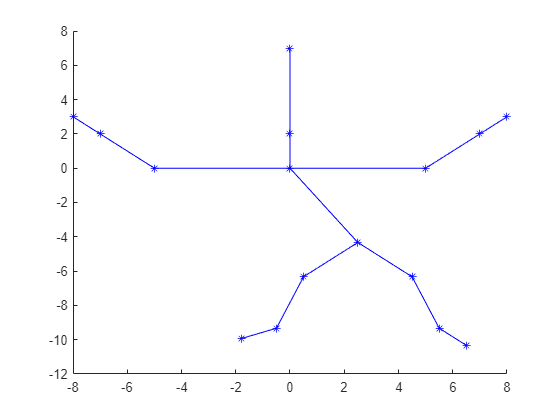


old_pos = cell2mat(skeleton(12));
new_pos = old_pos - old_pos(:,1);
new_pos = l_feet_rotation * new_pos;
new_pos = new_pos + old_pos(:,1);
skeleton(12) = mat2cell(new_pos,2,2);
% Plot the result
% Enter your code here

clf
figure(1)
hold on;
for i = 1:15
    tmp = cell2mat(skeleton(i));
    plot(tmp(1,1:end), tmp(2,1:end),'*b-')
end



% Section6: rotate right_thigh, right_lower_leg and right_feet
% Enter your code here
r_thigh_theta =-30

r_thigh_theta = -30

r_thigh_rotation = [cosd(r_thigh_theta), sind(r_thigh_theta); -sind(r_thigh_theta), cosd(r_thigh_theta)];

%rotationg left upperarm,
old_pos = cell2mat(skeleton(13));
new_pos = old_pos - old_pos(:,1); %move to 0,0 for rotation
new_pos = r_thigh_rotation * new_pos;
new_pos = new_pos + old_pos(:,1);
change = new_pos(:,2) - old_pos(:, 2);
skeleton(13) = mat2cell(new_pos,2,2);

%move left forearm and hand
skeleton(14) = mat2cell(cell2mat(skeleton(14)) + change,2,2);
skeleton(15) = mat2cell(cell2mat(skeleton(15)) + change,2,2);

%rotate and move left forearm
r_lower_theta =30

r_lower_theta = 30

r_fore_rotation = [cosd(r_lower_theta), sind(r_lower_theta); -sind(r_lower_theta), cosd(r_lower_theta)];
old_pos = cell2mat(skeleton(14));
new_pos = old_pos - old_pos(:,1); %move to 0,0 for rotation
new_pos = r_fore_rotation * new_pos;
new_pos = new_pos + old_pos(:,1);
move = new_pos(:,2) - old_pos(:, 2);
skeleton(14) = mat2cell(new_pos,2,2);
%move left hand
skeleton(15) = mat2cell(cell2mat(skeleton(15)) + move,2,2);
%rotating left forearm also rotates left hand by same amount

r_feet_theta =-30

r_feet_theta = -30

r_feet_rotation = [cosd(r_feet_theta), sind(r_feet_theta); -sind(r_feet_theta), cosd(r_feet_theta)]

r_feet_rotation =     0.8660   -0.5000
    0.5000    0.8660


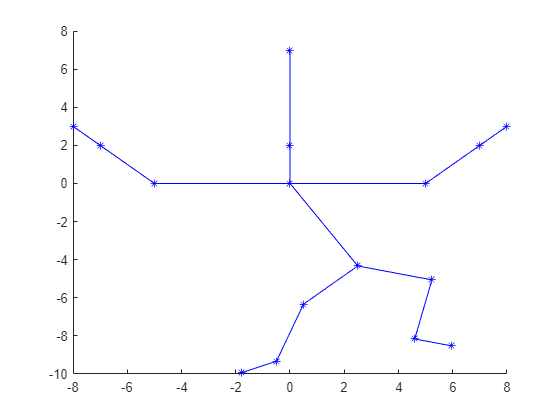


old_pos = cell2mat(skeleton(15));
new_pos = old_pos - old_pos(:,1);
new_pos = r_feet_rotation * new_pos;
new_pos = new_pos + old_pos(:,1);
skeleton(15) = mat2cell(new_pos,2,2);
% Plot the result
% Enter your code here

clf
figure(1)
hold on;
for i = 1:15
    tmp = cell2mat(skeleton(i));
    plot(tmp(1,1:end), tmp(2,1:end),'*b-')
end



% Section7: rotate head and neck
% Enter your code here
neck_theta =-30

neck_theta = -30

neck_rotation = [cosd(neck_theta), sind(neck_theta); -sind(neck_theta), cosd(neck_theta)];

%rotationg left upperarm,
movement = neck_rotation * cell2mat(skeleton(2));
change = movement - cell2mat(skeleton(2)); %save for using to move connected bones
skeleton(2) = mat2cell(movement,2,2);

change = change(:, 2); %x-axis rotation, hence only y coords change
skeleton(1) = mat2cell(cell2mat(skeleton(1)) + change,2,2);

head_theta =-20

head_theta = -20

head_rotation = [cosd(head_theta), sind(head_theta); -sind(head_theta), cosd(head_theta)]

head_rotation =     0.9397   -0.3420
    0.3420    0.9397


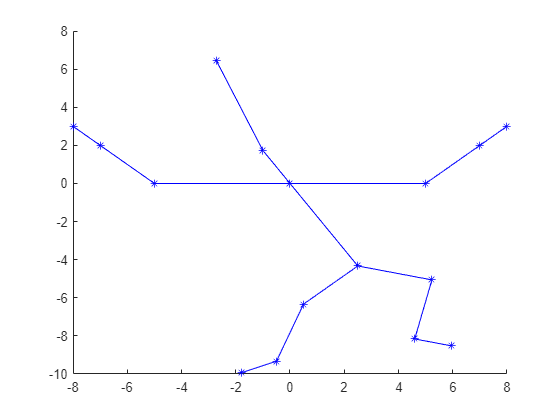


old_pos = cell2mat(skeleton(1));
new_pos = old_pos - old_pos(:,1);
new_pos = head_rotation * new_pos;
new_pos = new_pos + old_pos(:,1);
skeleton(1) = mat2cell(new_pos,2,2);

% Plot the result
% Enter your code here
clf
figure(1)
hold on;
for i = 1:15
    tmp = cell2mat(skeleton(i));
    plot(tmp(1,1:end), tmp(2,1:end),'*b-')
end